%johnny vastola Math 131,
clc
clear

1.

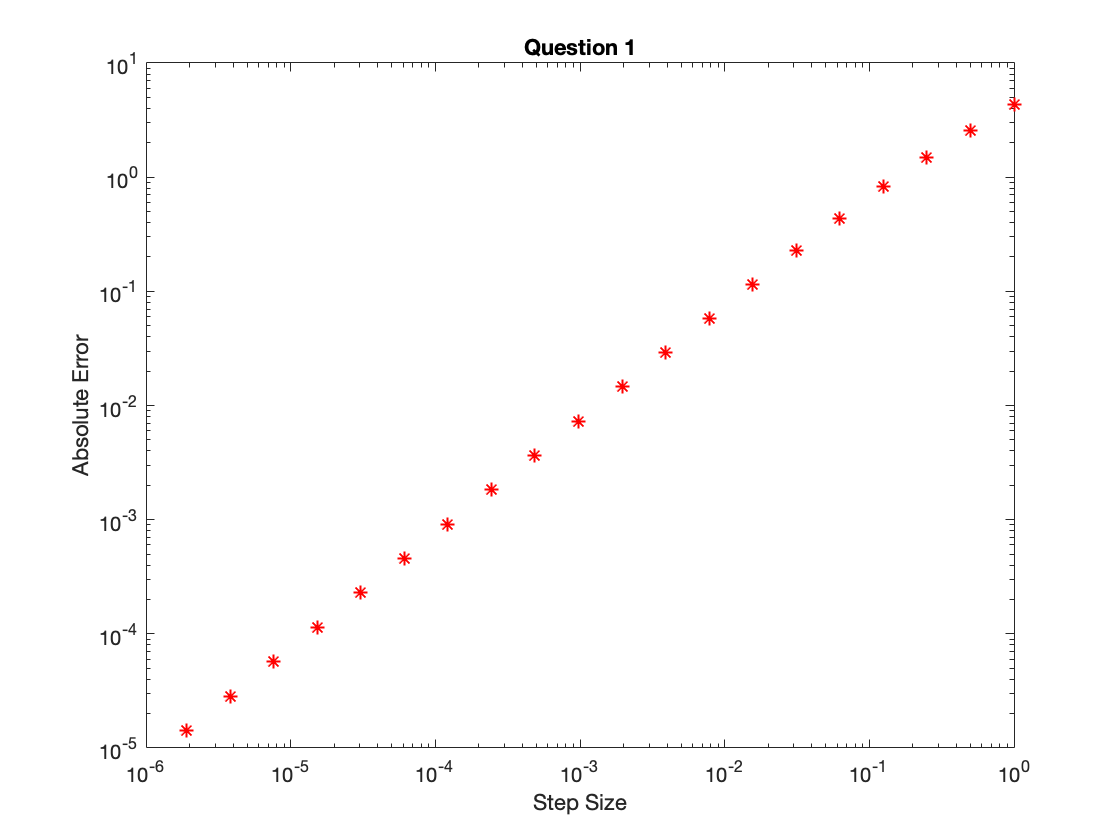

tstart=0;tend=2;
n= @(k) 2.^k;
actual= @(t) (t+1).^2-exp(t)/2;
init=0.5;
f= @(t,y) y-t^2+1;
actual(2);
for i=1:20
    N(i)=n(i);
    error(i)=abs(Euler(f,tstart,tend,n(i),init)-actual(tend));
    end
loglog(2./N,error,'r*');
title('Question 1');xlabel('Step Size');ylabel('Absolute Error');

2.

[t,y] = ode45(@(t,y) y-t^2+1,[0 2],.5)

t =          0
    0.0167
    0.0335
    0.0502
    0.0670
    0.1170
    0.1670
    0.2170
    0.2670
    0.3170


y =     0.5000
    0.5253
    0.5511
    0.5772
    0.6038
    0.6856
    0.7710
    0.8599
    0.9522
    1.0480


%45 time steps
abs(y(45)-actual(2))

ans = 4.0067e-07

Helper Functions

function u= Euler(f,tstart,tend,N,init)
t=linspace(tstart,tend,N);
h=(tend-tstart)/N;
u=init;
for i=1:N
    uold=u;
    u=uold+h*f(t(i),uold);
end
end
